# Análisis de Reducción de Dimensionalidad y Clasificación (MNIST)

## Carga y preprocesamiento de datos

clc; clear; close all;
rng(42); % Semilla para reproducibilidad
load('digits.mat');
[num_pixels, num_samples] = size(digits.image); % 784 x 10000
img_size = sqrt(num_pixels); % 28x28 imágenes

% Normalización (media 0, varianza 1)
mean_img = mean(digits.image, 2);
std_img = std(digits.image, 0, 2);
image_norm = (digits.image - mean_img) ./ (std_img + eps);

### Task 1: PCA - Viabilidad de reducción de dimensionalidad y reconstrucción

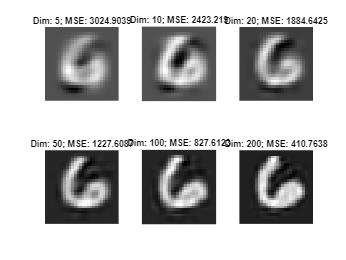

[coeff, score, latent] = pca(image_norm');

% Selección de dimensiones a probar
dims = [5, 10, 20, 50, 100, 200]; 
dims = dims(dims <= size(score, 2));

% Reconstrucción y cálculo del error MSE
mse_vals = zeros(size(dims));

figure;
for i = 1:length(dims)
    dim = dims(i); 
    reduced_data = score(:,1:dim) * coeff(:,1:dim)';
    reconstructed = (reduced_data' .* std_img) + mean_img;

    mse_vals(i) = mean((digits.image(:) - reconstructed(:)).^2);

    subplot(2, 3, i);
    imshow(reshape(reconstructed(:,1), img_size, img_size)', []);
    title(['Dim: ', num2str(dim), '; MSE: ', num2str(mse_vals(i))]);
end

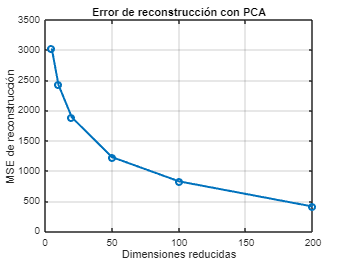

% Gráfica MSE vs Dimensiones
figure;
plot(dims, mse_vals, '-o', 'LineWidth', 2);
xlabel('Dimensiones reducidas');
ylabel('MSE de reconstrucción');
title('Error de reconstrucción con PCA');
grid on;

### Task 2: Clasificación usando k-NN (con reducción PCA)

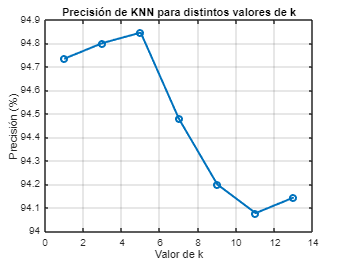

% Dividir datos (90% train, 10% test)
num_train = round(0.9 * num_samples);
indices = randperm(num_samples);
train_idx = indices(1:num_train);
test_idx = indices(num_train+1:end);

% Configuración KNN
[coeff, score, latent] = pca(digits.image');
d_pca_knn = 20;
X_train_knn = score(train_idx, 1:d_pca_knn);
Y_train_knn = digits.label(train_idx);
X_test_knn = score(test_idx, 1:d_pca_knn);
Y_test_knn = digits.label(test_idx);

% Evaluar diferentes valores de k
ks = [1, 3, 5, 7, 9, 11, 13];
accuracies_knn = zeros(1, length(ks));

for i = 1:length(ks)
    k = ks(i);
    
    % Validación cruzada
    cv = cvpartition(Y_train_knn, 'KFold', 10); % 5-fold cross-validation
    accuracy_k = zeros(cv.NumTestSets, 1);
    
    for j = 1:cv.NumTestSets
        train_cv = X_train_knn(training(cv, j), :);
        test_cv = X_train_knn(test(cv, j), :);
        Y_train_cv = Y_train_knn(training(cv, j));
        Y_test_cv = Y_train_knn(test(cv, j));
        
        Mdl = fitcknn(train_cv, Y_train_cv, 'NumNeighbors', k);
        Y_pred_cv = predict(Mdl, test_cv);
        accuracy_k(j) = mean(Y_pred_cv == Y_test_cv') * 100;
    end
    
    accuracies_knn(i) = mean(accuracy_k); % Promedio de la precisión de la validación cruzada
end

% Gráfica precisión vs k
figure;
plot(ks, accuracies_knn, '-o', 'LineWidth', 2);
xlabel('Valor de k');
ylabel('Precisión (%)');
title('Precisión de KNN para distintos valores de k');
grid on;



% Usamos un valor fijo de k = 5
X = score(:, 1:d_pca_knn);  % Datos transformados por PCA
Y = digits.label;

% Configuración de validación cruzada
num_reps = 5;  % Número de repeticiones para validación cruzada (puedes ajustarlo)
accuracy_knn_kfold = zeros(num_reps, 1);
training_times = zeros(num_reps, 1);
testing_times = zeros(num_reps, 1);

k = 5;

for j = 1:num_reps
    % Crear partición de HoldOut 90% train / 10% test
    cv = cvpartition(Y, 'HoldOut', 0.1);
    
    % Dividir los datos en train y test
    train_cv = X(training(cv), :);
    test_cv = X(test(cv), :);
    Y_train_cv = Y(training(cv));
    Y_test_cv = Y(test(cv));

    % Entrenamiento del modelo KNN
    tic;
    Mdl_knn = fitcknn(train_cv, Y_train_cv, 'NumNeighbors', k);
    training_times(j) = toc;

    % Testing del modelo KNN
    tic;
    Y_pred_knn_cv = predict(Mdl_knn, test_cv);
    testing_times(j) = toc;

    % Precisión de la validación cruzada (promedio)
    accuracy_knn_kfold(j) = mean(Y_pred_knn_cv == Y_test_cv') * 100;
end

% Precisión promedio de KNN (valores de k fijo)
accuracy_knn_pca = mean(accuracy_knn_kfold);
disp(['Precisión promedio KNN (validación cruzada): ', num2str(accuracy_knn_pca), '%']);

Precisión promedio KNN (validación cruzada): 94.98%



% Mostrar los tiempos promedio
disp('Tiempo promedio de entrenamiento por repeticiones (segundos):');

Tiempo promedio de entrenamiento por repeticiones (segundos):


t_training_knn_pca = mean(training_times);
disp(t_training_knn_pca);

    0.0075




disp('Tiempo promedio de testing por repeticiones (segundos):');

Tiempo promedio de testing por repeticiones (segundos):


t_testing_knn_pca = mean(testing_times);
disp(t_testing_knn_pca);

    0.0896



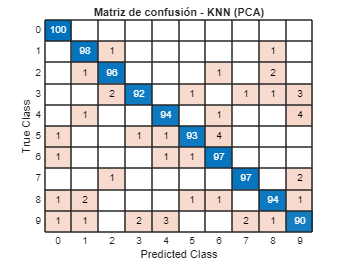


% Matriz de confusión KNN (última repetición)
figure;
confusionchart(Y_test_cv, Y_pred_knn_cv);
title('Matriz de confusión - KNN (PCA)');

### Task 3: Clasificación usando Bayes (con reducción PCA)

% PCA
d_pca_bayes = 50;
[coeff, score, latent] = pca(digits.image');
X = score(:, 1:d_pca_bayes);  % Datos transformados por PCA
Y = digits.label;

% División 90/10 usando HoldOut
num_reps = 10;  % Número de repeticiones para validación cruzada (como si fueran "folds")
accuracy_bayes_kfold = zeros(num_reps, 1);
training_times = zeros(num_reps, 1);
testing_times = zeros(num_reps, 1);

for j = 1:num_reps
    % Crear partición de HoldOut 90% train / 10% test
    cv = cvpartition(Y, 'HoldOut', 0.1);
    
    % Dividir los datos en train y test
    train_cv = X(training(cv), :);
    test_cv = X(test(cv), :);
    Y_train_cv = Y(training(cv));
    Y_test_cv = Y(test(cv));

    % Entrenamiento del modelo Bayesiano
    tic;
    Mdl_bayes = fitcnb(train_cv, Y_train_cv);
    training_times(j) = toc;

    % Testing del modelo Bayesiano
    tic;
    Y_pred_bayes_cv = predict(Mdl_bayes, test_cv);
    testing_times(j) = toc;

    % Precisión de la validación cruzada (promedio)
    accuracy_bayes_kfold(j) = mean(Y_pred_bayes_cv == Y_test_cv') * 100;
end

% Precisión promedio de la validación cruzada
accuracy_bayes_pca = mean(accuracy_bayes_kfold); 
disp(['Precisión Bayes (validación cruzada): ', num2str(accuracy_bayes_pca), '%']);

Precisión Bayes (validación cruzada): 87.2%



% Mostrar los tiempos promedio
disp('Tiempo promedio de entrenamiento por repeticiones (segundos):');

Tiempo promedio de entrenamiento por repeticiones (segundos):


t_training_bayes_pca = mean(training_times);
disp(t_training_bayes_pca);

    0.1839




disp('Tiempo promedio de testing por repeticiones (segundos):');

Tiempo promedio de testing por repeticiones (segundos):


t_testing_bayes_pca = mean(testing_times);
disp(t_testing_bayes_pca);

    0.1178



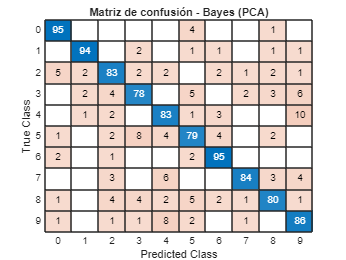


% Matriz de confusión Bayes (última repetición)
figure;
confusionchart(Y_test_cv, Y_pred_bayes_cv);
title('Matriz de confusión - Bayes (PCA)');

## Comprobación del error y los tiempos de cómputo según la dimensión del PCA

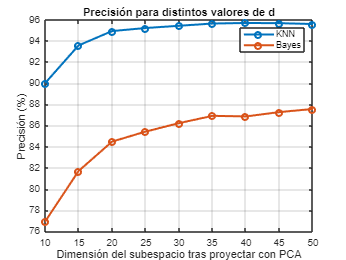


dim_pca_list = [10,15,20,25,30,35,40,45,50];

acc_knn_pca_list = [];
acc_bayes_pca_list = [];
t_training_knn_list = [];
t_testing_knn_list = [];
t_training_bayes_list = [];
t_testing_bayes_list = [];

[coeff, score, latent] = pca(digits.image');

for d_pca = dim_pca_list
    
    % Seleccionar datos de entrenamiento y prueba (usando d_pca componentes PCA)
    X_train_knn = score(train_idx, 1:d_pca);
    Y_train_knn = digits.label(train_idx);
    X_test_knn = score(test_idx, 1:d_pca);
    Y_test_knn = digits.label(test_idx);
    X_train_bayes = score(train_idx, 1:d_pca);
    Y_train_bayes = digits.label(train_idx);
    X_test_bayes = score(test_idx, 1:d_pca);
    Y_test_bayes = digits.label(test_idx);
    
    % Validación cruzada para KNN
    cv_knn = cvpartition(Y_train_knn, 'KFold', 5); % 5-fold cross-validation
    accuracy_knn_kfold = zeros(cv_knn.NumTestSets, 1);
    
    for j = 1:cv_knn.NumTestSets
        train_cv_knn = X_train_knn(training(cv_knn, j), :);
        Y_train_cv_knn = Y_train_knn(training(cv_knn, j));
        
        % Entrenar modelo KNN con k=3
        k = 3;
        tic;
        Mdl_knn = fitcknn(train_cv_knn, Y_train_cv_knn, 'NumNeighbors', k);
        t_training_knn_pca = toc;
        
        % Realizar predicción
        test_cv_knn = X_train_knn(test(cv_knn, j), :);
        Y_test_cv_knn = Y_train_knn(test(cv_knn, j));
        
        tic;
        Y_pred_knn = predict(Mdl_knn, test_cv_knn);
        t_testing_knn_pca = toc;
        
        % Calcular precisión
        accuracy_knn_kfold(j) = mean(Y_pred_knn == Y_test_cv_knn') * 100;
    end
    
    % Promedio de precisión KNN
    acc_knn_pca_list = [acc_knn_pca_list, mean(accuracy_knn_kfold)];
    t_training_knn_list = [t_training_knn_list, t_training_knn_pca];
    t_testing_knn_list = [t_testing_knn_list, t_testing_knn_pca];
    
    % Validación cruzada para Bayes
    cv_bayes = cvpartition(Y_train_bayes, 'KFold', 5); % 5-fold cross-validation
    accuracy_bayes_kfold = zeros(cv_bayes.NumTestSets, 1);
    
    for j = 1:cv_bayes.NumTestSets
        train_cv_bayes = X_train_bayes(training(cv_bayes, j), :);
        Y_train_cv_bayes = Y_train_bayes(training(cv_bayes, j));
        
        % Entrenar modelo Bayesiano
        tic;
        Mdl_bayes = fitcnb(train_cv_bayes, Y_train_cv_bayes);
        t_training_bayes_pca = toc;
        
        % Realizar predicción
        test_cv_bayes = X_train_bayes(test(cv_bayes, j), :);
        Y_test_cv_bayes = Y_train_bayes(test(cv_bayes, j));
        
        tic;
        Y_pred_bayes = predict(Mdl_bayes, test_cv_bayes);
        t_testing_bayes_pca = toc;
        
        % Calcular precisión
        accuracy_bayes_kfold(j) = mean(Y_pred_bayes == Y_test_cv_bayes') * 100;
    end
    
    % Promedio de precisión Bayes
    acc_bayes_pca_list = [acc_bayes_pca_list, mean(accuracy_bayes_kfold)];
    t_training_bayes_list = [t_training_bayes_list, t_training_bayes_pca];
    t_testing_bayes_list = [t_testing_bayes_list, t_testing_bayes_pca];
end

figure;
plot(dim_pca_list, acc_knn_pca_list, '-o', dim_pca_list, acc_bayes_pca_list, '-o', 'LineWidth', 2);
xlabel('Dimensión del subespacio tras proyectar con PCA');
ylabel('Precisión (%)');
title('Precisión para distintos valores de d');
legend('KNN', 'Bayes');
grid on;

### Task 7: Uso de LDA para reducción de dimensionalidad

### Task 8: Clusterización por clase usando K-means

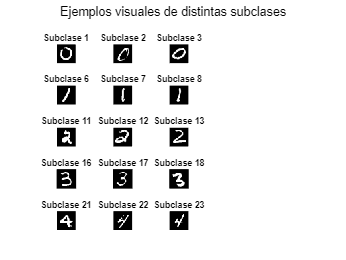

Precisión KNN sobre espacio LDA (validación cruzada): 95.60%


Tiempo promedio de entrenamiento KNN: 0.071675 segundos


Tiempo promedio de testing KNN: 0.12438 segundos


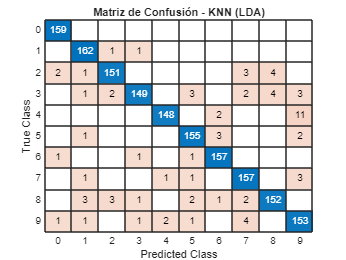

% --- Parámetros iniciales ---
N_subclasses = [3 3 3 3 3 5 4 4 5 5]; % Subclases por dígito
X = digits.image';  % Imágenes sin normalizar (cada fila una imagen)
Y = digits.label;

unique_labels = unique(Y);
num_classes = numel(unique_labels);

X_clustered = [];
Y_clustered = [];
original_labels = [];

% --- Clustering por subclases usando K-means ---
for i = 1:num_classes
    class_label = unique_labels(i);
    idx = find(Y == class_label);
    X_class = X(idx, :);

    n_sub = N_subclasses(i);
    [sub_idx, ~] = kmeans(X_class, n_sub, 'Replicates', 5);

    for j = 1:n_sub
        sub_idx_j = (sub_idx == j);
        X_sub = X_class(sub_idx_j, :);
        new_label = (i - 1) * max(N_subclasses) + j;

        X_clustered = [X_clustered; X_sub];
        Y_clustered = [Y_clustered; repmat(new_label, sum(sub_idx_j), 1)];
        original_labels = [original_labels; repmat(class_label, sum(sub_idx_j), 1)];
    end
end

% --- Visualización de ejemplos por subclase ---
img_size = sqrt(size(X, 2));
num_to_show = min(25, max(Y_clustered));
figure;
for i = 1:num_to_show
    idx = find(Y_clustered == i, 1);
    if ~isempty(idx)
        img = X_clustered(idx, :);
        subplot(5, 5, i);
        imshow(reshape(img, img_size, img_size)', []);
        title(['Subclase ', num2str(i)]);
    end
end
sgtitle('Ejemplos visuales de distintas subclases');

% --- LDA ---
lda_model = fitcdiscr(X_clustered, Y_clustered, 'DiscrimType', 'pseudoLinear');
class_means = lda_model.Mu';
X_centered = X_clustered - mean(X_clustered);
[U, ~, ~] = svd(class_means - mean(class_means, 2), 'econ');

num_subclasses_total = numel(unique(Y_clustered));
W_proj = U(:, 1:(num_subclasses_total - 1));
X_lda = X_centered * W_proj;

% --- División EXACTA: 9000 train / 1000 test ---
num_samples = size(X_lda, 1);
num_test = 1000;
num_train = num_samples - num_test;

indices = randperm(num_samples);
train_idx = indices(1:num_train);
test_idx = indices(num_train+1:end);

X_train_lda = X_lda(train_idx, :);
Y_train_true = original_labels(train_idx);

X_test_lda = X_lda(test_idx, :);
Y_test_true = original_labels(test_idx);

% --- KNN con LDA (validación cruzada sobre entrenamiento) ---
k = 5;
cv = cvpartition(Y_train_true, 'KFold', 10);

acc_knn_lda_cv = zeros(cv.NumTestSets, 1);
training_times_knn_lda = zeros(cv.NumTestSets, 1);
testing_times_knn_lda = zeros(cv.NumTestSets, 1);

for j = 1:cv.NumTestSets
    train_idx_cv = training(cv, j);
    test_idx_cv = test(cv, j);
    
    % Entrenamiento
    tic;
    Mdl_knn = fitcknn(X_train_lda(train_idx_cv, :), Y_train_true(train_idx_cv), 'NumNeighbors', k);
    training_times_knn_lda(j) = toc;

    % Predicción
    tic;
    Y_pred_cv = predict(Mdl_knn, X_train_lda(test_idx_cv, :));
    testing_times_knn_lda(j) = toc;

    % Precisión
    acc_knn_lda_cv(j) = mean(Y_pred_cv == Y_train_true(test_idx_cv)) * 100;
end

% --- Resultados de validación cruzada ---
acc_cv = mean(acc_knn_lda_cv);
t_train = mean(training_times_knn_lda);
t_test = mean(testing_times_knn_lda);

disp(['[CV] Precisión media: ', num2str(acc_cv, '%.2f'), '%']);
disp(['[CV] Tiempo medio entrenamiento: ', num2str(t_train, '%.4f'), ' s']);
disp(['[CV] Tiempo medio testing: ', num2str(t_test, '%.4f'), ' s']);

% --- Entrenamiento final sobre train y evaluación en test ---
Mdl_final = fitcknn(X_train_lda, Y_train_true, 'NumNeighbors', k);
Y_pred_test = predict(Mdl_final, X_test_lda);
acc_test = mean(Y_pred_test == Y_test_true) * 100;

disp(['[TEST] Precisión final en 1000 muestras: ', num2str(acc_test, '%.2f'), '%']);

% --- Matriz de Confusión sobre test ---
figure;
confusionchart(Y_test_true, Y_pred_test);
title('Matriz de Confusión - KNN (LDA)');

### Task 3(b): Bayes con LDA

Precisión Bayes sobre espacio LDA (validación cruzada): 87.20%


Tiempo promedio de entrenamiento Bayes: 0.103 segundos


Tiempo promedio de testing Bayes: 0.078031 segundos


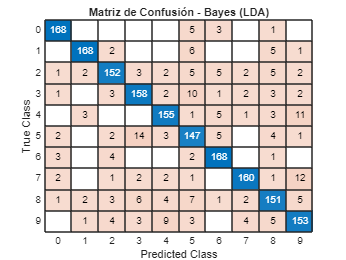

% --- Clasificador Bayesiano con validación cruzada sobre conjunto de entrenamiento (9000) ---
cv = cvpartition(Y_train_true, 'KFold', 10); % 5-fold cross-validation

acc_bayes_lda_cv = zeros(cv.NumTestSets, 1); 
training_times_bayes_lda = zeros(cv.NumTestSets, 1); 
testing_times_bayes_lda = zeros(cv.NumTestSets, 1); 

for j = 1:cv.NumTestSets
    train_idx_cv = training(cv, j);
    test_idx_cv = test(cv, j);
    
    % Entrenamiento Bayes
    tic;
    Mdl_bayes = fitcnb(X_train_lda(train_idx_cv, :), Y_train_true(train_idx_cv));
    training_times_bayes_lda(j) = toc;

    % Predicción
    tic;
    Y_pred_cv = predict(Mdl_bayes, X_train_lda(test_idx_cv, :));
    testing_times_bayes_lda(j) = toc;

    % Precisión
    acc_bayes_lda_cv(j) = mean(Y_pred_cv == Y_train_true(test_idx_cv)) * 100;
end

% --- Resultados de validación cruzada ---
acc_bayes_cv = mean(acc_bayes_lda_cv);
t_train_bayes = mean(training_times_bayes_lda);
t_test_bayes = mean(testing_times_bayes_lda);

disp(['[CV - BAYES] Precisión media: ', num2str(acc_bayes_cv, '%.2f'), '%']);
disp(['[CV - BAYES] Tiempo medio entrenamiento: ', num2str(t_train_bayes, '%.4f'), ' s']);
disp(['[CV - BAYES] Tiempo medio testing: ', num2str(t_test_bayes, '%.4f'), ' s']);

% --- Evaluación final en test (1000 imágenes) ---
Mdl_bayes_final = fitcnb(X_train_lda, Y_train_true);  % Entrenar con todo el training (9000)
Y_pred_test_bayes = predict(Mdl_bayes_final, X_test_lda);  % Predecir test (1000)
acc_test_bayes = mean(Y_pred_test_bayes == Y_test_true) * 100;

disp(['[TEST - BAYES] Precisión final en test (1000 imágenes): ', num2str(acc_test_bayes, '%.2f'), '%']);

% --- Matriz de confusión Bayes sobre test final ---
figure;
confusionchart(Y_test_true, Y_pred_test_bayes);
title('Matriz de Confusión - Bayes (LDA)');

### PCA+ LDA

N_subclasses = [3 3 3 3 3 5 4 4 5 5]; % Número de subclases por dígito (0-9)
X = digits.image'; % Usamos las imágenes sin normalizar
Y = digits.label;

unique_labels = unique(Y);
num_classes = numel(unique_labels);

X_clustered = [];
Y_clustered = [];
original_labels = [];

for i = 1:num_classes
    class_label = unique_labels(i);
    idx = find(Y == class_label);
    X_class = X(idx, :);

    n_sub = N_subclasses(i);
    [sub_idx, ~] = kmeans(X_class, n_sub, 'Replicates', 5);

    for j = 1:n_sub
        sub_idx_j = (sub_idx == j);
        X_sub = X_class(sub_idx_j, :);
        new_label = (i - 1) * max(N_subclasses) + j;

        X_clustered = [X_clustered; X_sub];
        Y_clustered = [Y_clustered; repmat(new_label, sum(sub_idx_j), 1)];
        original_labels = [original_labels; repmat(class_label, sum(sub_idx_j), 1)];
    end
end

% === PCA antes de LDA ===
[coeff_pca, score_pca] = pca(X_clustered);
num_components_pca = 30;
X_pca = score_pca(:, 1:num_components_pca);

% === Aplicar LDA sobre datos proyectados con PCA ===
lda_model = fitcdiscr(X_pca, Y_clustered, 'DiscrimType', 'pseudoLinear');
class_means = lda_model.Mu';
X_centered = X_pca - mean(X_pca);
[U, ~, ~] = svd(class_means - mean(class_means, 2), 'econ');

num_subclasses_total = numel(unique(Y_clustered));
W_proj = U(:, 1:(num_subclasses_total - 1));
X_lda = X_centered * W_proj;

% === División en train/test para LDA ===
num_samples = size(X_lda, 1);
num_train = round(0.9 * num_samples);
indices = randperm(num_samples);
train_idx = indices(1:num_train);
test_idx = indices(num_train+1:end);

X_train_lda = X_lda(train_idx, :);
X_test_lda = X_lda(test_idx, :);
Y_train_true = original_labels(train_idx);
Y_test_true = original_labels(test_idx);


% === KNN ===
k = 5;
num_folds = 5;

acc_knn_lda_cv = zeros(num_folds, 1);
training_times_knn_lda = zeros(num_folds, 1);
testing_times_knn_lda = zeros(num_folds, 1);

Y_pred_knn_lda_final = [];
Y_test_knn_lda_final = [];

for j = 1:num_folds
    % HoldOut 90% train, 10% test aleatorio en cada pliegue
    cv = cvpartition(Y_train_true, 'HoldOut', 0.1);

    train_idx_cv = training(cv);
    test_idx_cv = test(cv);

    % Entrenamiento
    tic;
    Mdl_knn_lda = fitcknn(X_train_lda(train_idx_cv, :), Y_train_true(train_idx_cv), 'NumNeighbors', k);
    training_times_knn_lda(j) = toc;

    % Testing
    tic;
    Y_pred = predict(Mdl_knn_lda, X_train_lda(test_idx_cv, :));
    testing_times_knn_lda(j) = toc;

    % Precisión
    acc_knn_lda_cv(j) = mean(Y_pred == Y_train_true(test_idx_cv)) * 100;

    % Guardar el último fold para matriz de confusión
    if j == num_folds
        Y_pred_knn_lda_final = Y_pred;
        Y_test_knn_lda_final = Y_train_true(test_idx_cv);
    end
end

% Resultados promedio
acc_knn_ldapca_mean = mean(acc_knn_lda_cv);
t_training_knn_ldapca = mean(training_times_knn_lda);
t_testing_knn_ldapca = mean(testing_times_knn_lda);

% Mostrar resultados
disp(['Precisión KNN sobre espacio PCA+LDA (validación cruzada 90/10): ', num2str(acc_knn_ldapca_mean, '%.2f'), '%']);

Precisión KNN sobre espacio PCA+LDA (validación cruzada 90/10): 95.56%


disp(['Tiempo promedio de entrenamiento KNN (PCA+LDA): ', num2str(t_training_knn_ldapca), ' segundos']);

Tiempo promedio de entrenamiento KNN (PCA+LDA): 0.010466 segundos


disp(['Tiempo promedio de testing KNN (PCA+LDA): ', num2str(t_testing_knn_ldapca), ' segundos']);

Tiempo promedio de testing KNN (PCA+LDA): 0.065483 segundos


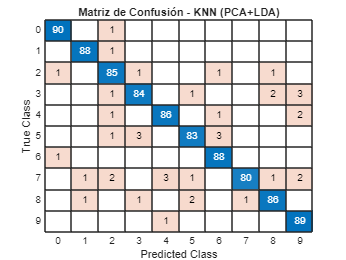


% Matriz de confusión con el último fold
figure;
confusionchart(Y_test_knn_lda_final, Y_pred_knn_lda_final);
title('Matriz de Confusión - KNN (PCA+LDA)');



% === Clasificador Bayesiano sobre PCA+LDA ===
num_folds = 5;

acc_bayes_lda_cv = zeros(num_folds, 1);
training_times_bayes_lda = zeros(num_folds, 1);
testing_times_bayes_lda = zeros(num_folds, 1);

Y_pred_bayes_lda_final = [];
Y_test_bayes_lda_final = [];

for j = 1:num_folds
    % HoldOut 90% train, 10% test aleatorio en cada pliegue
    cv = cvpartition(Y_train_true, 'HoldOut', 0.1);

    train_idx_cv = training(cv);
    test_idx_cv = test(cv);

    % Entrenamiento
    tic;
    Mdl_bayes_lda = fitcnb(X_train_lda(train_idx_cv, :), Y_train_true(train_idx_cv));
    training_times_bayes_lda(j) = toc;

    % Testing
    tic;
    Y_pred = predict(Mdl_bayes_lda, X_train_lda(test_idx_cv, :));
    testing_times_bayes_lda(j) = toc;

    % Precisión
    acc_bayes_lda_cv(j) = mean(Y_pred == Y_train_true(test_idx_cv)) * 100;

    % Guardar el último fold para matriz de confusión
    if j == num_folds
        Y_pred_bayes_lda_final = Y_pred;
        Y_test_bayes_lda_final = Y_train_true(test_idx_cv);
    end
end

% Resultados promedio
acc_bayes_ldapca_mean = mean(acc_bayes_lda_cv);
t_training_bayes_ldapca = mean(training_times_bayes_lda);
t_testing_bayes_ldapca = mean(testing_times_bayes_lda);

% Mostrar resultados
disp(['Precisión Bayes sobre espacio PCA+LDA (validación cruzada 90/10): ', num2str(acc_bayes_ldapca_mean, '%.2f'), '%']);

Precisión Bayes sobre espacio PCA+LDA (validación cruzada 90/10): 85.18%


disp(['Tiempo promedio de entrenamiento Bayes (PCA+LDA): ', num2str(t_training_bayes_ldapca), ' segundos']);

Tiempo promedio de entrenamiento Bayes (PCA+LDA): 0.034636 segundos


disp(['Tiempo promedio de testing Bayes (PCA+LDA): ', num2str(t_testing_bayes_ldapca), ' segundos']);

Tiempo promedio de testing Bayes (PCA+LDA): 0.038811 segundos


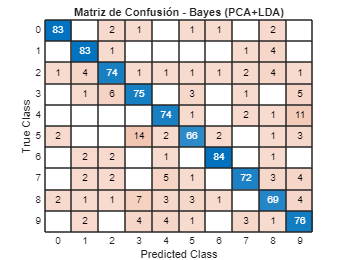


% Matriz de confusión con el último fold
figure;
confusionchart(Y_test_bayes_lda_final, Y_pred_bayes_lda_final);
title('Matriz de Confusión - Bayes (PCA+LDA)');

## Comparación PCA vs LDA vs PCA_LDA

% Comparación PCA vs LDA vs PCA+LDA

% Métodos a comparar
metodos = {'PCA'; 'LDA'; 'PCA+LDA'};

% Precisión de KNN y Bayes para cada método
precision_knn = [accuracy_knn_pca; acc_knn_lda; acc_knn_ldapca_mean];
precision_bayes = [accuracy_bayes_pca; acc_bayes_lda; acc_bayes_ldapca_mean];

% Tiempo de entrenamiento para cada clasificador y método
tiempo_entrenamiento_knn = [t_training_knn_pca; t_training_knn_lda; t_training_knn_ldapca];
tiempo_test_knn = [t_testing_knn_pca; t_testing_knn_lda; t_testing_bayes_ldapca];

tiempo_entrenamiento_bayes = [t_training_bayes_pca; t_training_bayes_lda; t_training_bayes_ldapca];
tiempo_test_bayes = [t_testing_bayes_pca; t_testing_bayes_lda; t_testing_bayes_ldapca];

% Crear tabla comparativa
T = table(metodos, precision_knn, precision_bayes, ...
          tiempo_entrenamiento_knn, tiempo_test_knn, ...
          tiempo_entrenamiento_bayes, tiempo_test_bayes);
disp(T);

      metodos      precision_knn    precision_bayes    tiempo_entrenamiento_knn    tiempo_test_knn    tiempo_entrenamiento_bayes    tiempo_test_bayes
    ___________    _____________    _______________    ________________________    _______________    __________________________    _________________

    {'PCA'    }        94.98              87.2                0.0064362                0.17297                 0.054712                  0.23139     
    {'LDA'    }       94.617            85.989                 0.023479                0.14411                 0.075878                  0.08917     
    {'PCA+LDA'}       95.556            85.178                 0.010466               0.038811                 0.034636                 0.038811     



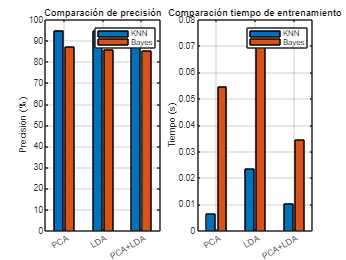


% Gráfico de precisión
figure;
subplot(1,2,1);
bar([precision_knn, precision_bayes]);
set(gca, 'XTickLabel', metodos);
ylabel('Precisión (%)');
legend('KNN', 'Bayes');
title('Comparación de precisión');
grid on;

% Gráfico de tiempo de entrenamiento
subplot(1,2,2);
bar([tiempo_entrenamiento_knn, tiempo_entrenamiento_bayes]);
set(gca, 'XTickLabel', metodos);
ylabel('Tiempo (s)');
legend('KNN', 'Bayes');
title('Comparación tiempo de entrenamiento');
grid on;

## Cálculo de la precisión en función del número de subclases (asumiendo todas iguales)


% Datos originales normalizados (antes del PCA)
X = digits.image'; % tamaño: 10000 x 784
Y = digits.label; % etiquetas originales

unique_labels = unique(Y);
num_classes = numel(unique_labels);


% Variables para almacenar los resultados
acc_knn_lda_all = zeros(5, 1);
acc_bayes_lda_all = zeros(5, 1);
num_subclasses_total_all = zeros(5, 1);

% Bucle para cambiar el número de subclases
for idx = 1:7
    N_subclasses = idx;
    X_clustered = [];
    Y_clustered = [];
    original_labels = [];

    % Clusterización por clase
    for i = 1:num_classes
        class_label = unique_labels(i);
        idx_class = find(Y == class_label);
        X_class = X(idx_class, :);

        n_sub = N_subclasses;
        [sub_idx, ~] = kmeans(X_class, n_sub, 'Replicates', 5);

        for j = 1:n_sub
            sub_idx_j = (sub_idx == j);
            X_sub = X_class(sub_idx_j, :);

            new_label = (i - 1) * max(N_subclasses) + j;

            X_clustered = [X_clustered; X_sub];
            Y_clustered = [Y_clustered; repmat(new_label, sum(sub_idx_j), 1)];
            original_labels = [original_labels; repmat(class_label, sum(sub_idx_j), 1)];
        end
    end

    % LDA usando las nuevas subclases (task 7)
    lda_model = fitcdiscr(X_clustered, Y_clustered, 'DiscrimType', 'pseudoLinear');

    % Extraer medias de cada clase
    class_means = lda_model.Mu';  % columnas: clases, filas: características

    % Centrar los datos
    X_centered = X_clustered - mean(X_clustered);

    % LDA con SVD sobre las medias centradas
    [U,~,~] = svd(class_means - mean(class_means, 2), 'econ');

    % Proyección LDA a (num_subclases_totales - 1)
    num_subclasses_total = numel(unique(Y_clustered));
    W_proj = U(:, 1:(num_subclasses_total - 1));
    X_lda = X_centered * W_proj;

    % División en train/test
    num_samples = size(X_lda, 1);
    num_train = round(0.8 * num_samples);
    indices = randperm(num_samples);
    train_idx = indices(1:num_train);
    test_idx = indices(num_train+1:end);

    % Datos LDA
    X_train_lda = X_lda(train_idx, :);
    X_test_lda = X_lda(test_idx, :);

    % Etiquetas verdaderas originales (para medir precisión)
    Y_train_true = original_labels(train_idx);
    Y_test_true = original_labels(test_idx);

    % KNN (LDA)
    k = 3;
    tic;
    Mdl_knn_lda = fitcknn(X_train_lda, Y_train_true, 'NumNeighbors', k);
    t_training_knn_lda = toc;
    tic;
    Y_pred_knn_lda = predict(Mdl_knn_lda, X_test_lda);
    t_testing_knn_lda = toc;
    acc_knn_lda = mean(Y_pred_knn_lda == Y_test_true) * 100;

    disp(['Precisión KNN sobre espacio LDA para N_subclases = ', num2str(N_subclasses), ': ', num2str(acc_knn_lda, '%.2f'), '%']);
    
% Precisión de Bayes (LDA)
    Mdl_bayes_lda = fitcnb(X_train_lda, Y_train_true);
    Y_pred_bayes_lda = predict(Mdl_bayes_lda, X_test_lda);
    acc_bayes_lda = mean(Y_pred_bayes_lda == Y_test_true) * 100;
    
    disp(['Precisión Bayes sobre espacio LDA para N_subclases = ', num2str(N_subclasses), ': ', num2str(acc_bayes_lda, '%.2f'), '%']);

    % Almacenar precisión y número total de subclases
    acc_knn_lda_all(idx) = acc_knn_lda;
    acc_bayes_lda_all(idx) = acc_bayes_lda;
    num_subclasses_total_all(idx) = num_subclasses_total;
end

Precisión KNN sobre espacio LDA para N_subclases = 1: 90.00%


Precisión Bayes sobre espacio LDA para N_subclases = 1: 83.15%


Precisión KNN sobre espacio LDA para N_subclases = 2: 94.65%


Precisión Bayes sobre espacio LDA para N_subclases = 2: 84.95%


Precisión KNN sobre espacio LDA para N_subclases = 3: 95.60%


Precisión Bayes sobre espacio LDA para N_subclases = 3: 87.05%


Precisión KNN sobre espacio LDA para N_subclases = 4: 96.70%


Precisión Bayes sobre espacio LDA para N_subclases = 4: 87.50%


Precisión KNN sobre espacio LDA para N_subclases = 5: 95.90%


Precisión Bayes sobre espacio LDA para N_subclases = 5: 85.75%


Precisión KNN sobre espacio LDA para N_subclases = 6: 95.80%


Precisión Bayes sobre espacio LDA para N_subclases = 6: 86.85%


Precisión KNN sobre espacio LDA para N_subclases = 7: 95.35%


Precisión Bayes sobre espacio LDA para N_subclases = 7: 87.00%


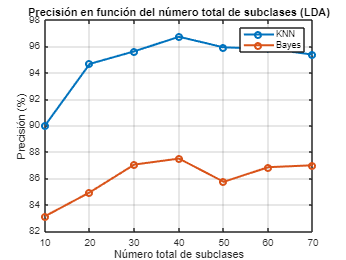

% Graficar la precisión de KNN y Bayes en función de N_subclases
figure;
plot(num_subclasses_total_all, acc_knn_lda_all, '-o', 'Linewidth', 2, 'DisplayName', 'KNN');
hold on;
plot(num_subclasses_total_all, acc_bayes_lda_all, '-o', 'Linewidth', 2, 'DisplayName', 'Bayes');
xlabel('Número total de subclases');
ylabel('Precisión (%)');
title('Precisión en función del número total de subclases (LDA)');
legend show;
grid on;